clear all;
close all;

%% PARAMETRES
M_1_2= 2;
M_3= 4;
Fe= 24000;
Rb= 6000;
Tb= 1/Rb;
T_3= Tb * log2(M_3);
R_3= 1/T_3;
Ns_3= Fe/R_3;
Ns_1_2 = Fe/Rb;

%% Filtres de mise en forme
h_1_2 = ones(1, Ns_1_2);
h_3= ones(1, Ns_3);

%% Filtres de réception
hr_1 = fliplr(h_1_2);                                         
hr_2 = fliplr([ones(1, Ns_1_2/2), zeros(1, Ns_1_2/2)]);      
hr_3 = fliplr(h_3);                                           

%% Valeurs Eb/N0
tab_Eb_sur_N0_dB= 0:6;
tab_Eb_sur_N0_lin= 10.^(tab_Eb_sur_N0_dB/10);

%% Initialisation TEB/SER
TEB_simu_1=zeros(1, length(tab_Eb_sur_N0_dB));
TEB_simu_2=zeros(1, length(tab_Eb_sur_N0_dB));
TEB_simu_3=zeros(1, length(tab_Eb_sur_N0_dB));
SER_simu_3=zeros(1, length(tab_Eb_sur_N0_dB));
TEB_th_1=zeros(1, length(tab_Eb_sur_N0_dB));
TEB_th_2=zeros(1, length(tab_Eb_sur_N0_dB));
TEB_th_3=zeros(1, length(tab_Eb_sur_N0_dB));
SER_th_3=zeros(1, length(tab_Eb_sur_N0_dB));

N_bit_block = 2000;


%% Chaine 1 - sans bruit
bits_test= randi([0,1], 1, N_bit_block);
symboles_test= 2*bits_test-1;
diracs_test= kron(symboles_test, [1 zeros(1, Ns_1_2-1)]);
signal_emis_test= filter(h_1_2, 1, diracs_test);

signal_filtre_test=filter(hr_1, 1, signal_emis_test);
t0_test=Ns_1_2;
signal_echantillonne_test=signal_filtre_test(t0_test:Ns_1_2:end);
nb_symb_test=min(length(signal_echantillonne_test), length(bits_test));
signal_echantillonne_test=signal_echantillonne_test(1:nb_symb_test);

symboles_decides_test=sign(signal_echantillonne_test);
bits_decides_test=(symboles_decides_test + 1)/2;
TEB_no_noise_1=sum(bits_test(1:nb_symb_test) ~= bits_decides_test)/nb_symb_test;
fprintf('Chaine 1 - TEB sans bruit = %e (doit etre 0)\n', TEB_no_noise_1);

Chaine 1 - TEB sans bruit = 0.000000e+00 (doit etre 0)



%% Chaine 2 - sans bruit
bits_test=randi([0,1], 1, N_bit_block);
symboles_test=2*bits_test-1;
diracs_test=kron(symboles_test, [1 zeros(1, Ns_1_2-1)]);
signal_emis_test =filter(h_1_2, 1, diracs_test);

signal_filtre_test=filter(hr_2, 1, signal_emis_test);
t0_test= Ns_1_2;
signal_echantillonne_test= signal_filtre_test(t0_test:Ns_1_2:end);
nb_symb_test= min(length(signal_echantillonne_test), length(bits_test));
signal_echantillonne_test =signal_echantillonne_test(1:nb_symb_test);

symboles_decides_test=sign(signal_echantillonne_test);
bits_decides_test=(symboles_decides_test + 1)/2;
TEB_no_noise_2=sum(bits_test(1:nb_symb_test) ~= bits_decides_test)/nb_symb_test;
fprintf('Chaine 2 - TEB sans bruit = %e (doit etre 0)\n', TEB_no_noise_2);

Chaine 2 - TEB sans bruit = 0.000000e+00 (doit etre 0)



%% Chaine 3 - sans bruit
bits_test= randi([0,1], 1, N_bit_block);
symboles_test = (2 * bi2de(reshape(bits_test, 2, length(bits_test)/2).', 'left-msb') - 3).';
diracs_test= kron(symboles_test, [1 zeros(1, Ns_3-1)]);
signal_emis_test= filter(h_3, 1, diracs_test);
signal_emis_test= signal_emis_test(:).';

signal_filtre_test= filter(hr_3, 1, signal_emis_test);
t0_test= Ns_3;
signal_echantillonne_test = signal_filtre_test(t0_test:Ns_3:end);
r_test= signal_echantillonne_test/Ns_3;
nb_symb_test= min(length(r_test), length(symboles_test));
r_test= r_test(1:nb_symb_test);

symboles_decides_test = zeros(1, nb_symb_test);
symboles_decides_test(r_test < -2)= -3;
symboles_decides_test(r_test >= -2 & r_test < 0)= -1;
symboles_decides_test(r_test >= 0  & r_test < 2)=  1;
symboles_decides_test(r_test >= 2)=  3;

bits_decides_test = reshape(de2bi((symboles_decides_test + 3)/2, 2, 'left-msb').', 1, length(bits_test));
nb_bits_test= nb_symb_test*2;
TEB_no_noise_3= sum(bits_test(1:nb_bits_test) ~= bits_decides_test(1:nb_bits_test)) / nb_bits_test;
fprintf('Chaine 3 - TEB sans bruit = %e (doit etre 0)\n', TEB_no_noise_3);

Chaine 3 - TEB sans bruit = 0.000000e+00 (doit etre 0)



%% Chaine 1 

for indice_Eb_sur_N0=0:length(tab_Eb_sur_N0_dB)-1
    %Valeur testée
    Eb_sur_N0_dB=tab_Eb_sur_N0_dB(indice_Eb_sur_N0+1);
    %Compteurs (erreurs, nombre de boucles)
    nb_erreurs_1=0;
    compteur_1=0;
    %Variable de cumul pour le TEB
    TEB_simu_cumu_1=0;
    
    %BOUCLE SUR LE NOMBRE D'ERREURS (voir précision sur la mesure du TEB)
    while(nb_erreurs_1<1000)
        
        %MODULATEUR BANDE DE BASE
        %-----------------------------------------------------------------------
        %Information binaire
        bits=randi([0,1],1,N_bit_block);
        %Mapping binaire à moyenne nulle
        symboles= 2*bits - 1;
        %Suéchantillonnage
        diracs=kron(symboles,[1 zeros(1, Ns_1_2-1)]);
        %Filtrage de mise en forme
        signal_emis=filter(h_1_2,1,diracs);

        %CANAL DE PROPAGATION AWGN
        %----------------------------------------------------------------------
        %Puissance du signal
        Pr=mean(abs(signal_emis).^2);
        %Puissance du bruit
        Eb_sur_NO_lineair = 10.^(Eb_sur_N0_dB/10);
        Pb=1/2*erfc(sqrt(Eb_sur_NO_lineair)); % probabilité de bit
        %Génération du bruit
        sigma_n = Pr*Ns_1_2/(2*log2(M_1_2)*Eb_sur_NO_lineair);
        bruit=sqrt(sigma_n)*randn(1,length(signal_emis));
        %Ajout du bruit
        signal_recu=signal_emis+bruit;

        %DEMODULATEUR BANDE DE BASE
        %---------------------------------------------------------------------
        %Filtrage de réception
        signal_filtre=filter(hr_1,1,signal_recu);
        %Choix de t0
        t0=Ns_1_2;
        %Echantillonnage
        signal_echantillonne=signal_filtre(t0:Ns_1_2:end);
        %Décisions
        symboles_decides= sign(signal_echantillonne);
        %Demapping
        bits_decides= (symboles_decides+1)/2;
        %Estimation du TEB pour cette boucle
        nb_erreurs_1=nb_erreurs_1+ sum(bits ~= bits_decides);
        compteur_1=compteur_1+1;
    end
    %Update du TEB théorique
    TEB_th_1(indice_Eb_sur_N0+1) = Pb;
    TEB_simu_cumul_1=nb_erreurs_1/N_bit_block;
    %TEB SIMULE POUR LA VALEUR TESTEE DE Eb/N0
    TEB_simu_1(indice_Eb_sur_N0+1)= TEB_simu_cumul_1/compteur_1;
end
    


%% Chaine 2
for indice_Eb_sur_N0=0:length(tab_Eb_sur_N0_dB)-1
    %Valeur testée
    Eb_sur_N0_dB=tab_Eb_sur_N0_dB(indice_Eb_sur_N0+1);
    %Compteurs (erreurs, nombre de boucles)
    nb_erreurs_2=0;
    compteur_2=0;
    %Variable de cumul pour le TEB
    TEB_simu_cumul_2=0;
    
    %BOUCLE SUR LE NOMBRE D'ERREURS (voir précision sur la mesure du TEB)
    while(nb_erreurs_2<1000)
        
        %MODULATEUR BANDE DE BASE
        %-----------------------------------------------------------------------
        %Information binaire
        bits=randi([0,1],1,N_bit_block);
        %Mapping binaire à moyenne nulle
        symboles= 2*bits - 1;
        %Suéchantillonnage
        diracs=kron(symboles,[1 zeros(1, Ns_1_2-1)]);
        %Filtrage de mise en forme
        signal_emis=filter(h_1_2,1,diracs);

        %CANAL DE PROPAGATION AWGN
        %----------------------------------------------------------------------
        %Puissance du signal
        Pr=mean(abs(signal_emis).^2);
        %Puissance du bruit
        Eb_sur_NO_lineair = 10.^(Eb_sur_N0_dB/10);
        Pb_2 = 1/2 * erfc(sqrt(Eb_sur_NO_lineair)); % probabilité de bit
        %Génération du bruit
        sigma_n = Pr*Ns_1_2/(2*log2(M_1_2)*Eb_sur_NO_lineair);
        bruit=sqrt(sigma_n)*randn(1,length(signal_emis));
        %Ajout du bruit
        signal_recu=signal_emis+bruit;

        %DEMODULATEUR BANDE DE BASE
        %---------------------------------------------------------------------
        %Filtrage de réception
        signal_filtre=filter(hr_2,1,signal_recu);
        %Choix de t0
        t0=Ns_1_2;
        %Echantillonnage
        signal_echantillonne=signal_filtre(t0:Ns_1_2:end);
        %Décisions
        symboles_decides= sign(signal_echantillonne);
        %Demapping
        bits_decides= (symboles_decides+1)/2;
        %Estimation du TEB pour cette boucle
        nb_erreurs_2=nb_erreurs_2+ sum(bits ~= bits_decides);
        compteur_2=compteur_2+1;
    end
    TEB_th_2(indice_Eb_sur_N0+1) = Pb_2;
    TEB_simu_cumul_2=nb_erreurs_2/N_bit_block;
    %TEB SIMULE POUR LA VALEUR TESTEE DE Eb/N0
    TEB_simu_2(indice_Eb_sur_N0+1)= TEB_simu_cumul_2/compteur_2;
end



%% CHAINE 3 - version corrigée

for indice_Eb_sur_N0 = 0:length(tab_Eb_sur_N0_dB)-1

    Eb_sur_N0_dB = tab_Eb_sur_N0_dB(indice_Eb_sur_N0+1); 
    Eb_sur_N0_lin = 10^(Eb_sur_N0_dB/10);
    nb_erreurs_3 = 0;
    nb_erreurs_symboles_3 = 0;
    compteur_3 = 0;
    while nb_erreurs_3 < 1000
        
        %% Modulateur
        
        bits = randi([0,1], 1, N_bit_block);
        symboles = (2 * bi2de(reshape(bits, 2, length(bits)/2).', 'left-msb') - 3).';   
        diracs = kron(symboles, [1 zeros(1, Ns_3-1)]);
        signal_emis = filter(h_3, 1, diracs);
        signal_emis = signal_emis(:).';
        %% Canal AWGN
        Pr = mean(abs(signal_emis).^2);
        sigma_n_sq = (Pr * Ns_3) / (2 * log2(M_3) * Eb_sur_N0_lin);
        bruit = sqrt(sigma_n_sq) * randn(1, length(signal_emis));
        signal_recu = signal_emis + bruit;
        %% Démodulateur
        signal_filtre = filter(hr_3, 1, signal_recu);     
        t0 = Ns_3;        
        signal_echantillonne = signal_filtre(t0:Ns_3:end);        
        r = signal_echantillonne / Ns_3;        
        nb_symb = min(length(r), length(symboles));
        r = r(1:nb_symb);
        %% Décision par distance minimale (même méthode que 3_2)
        diff_mat = [abs(r + 3); abs(r + 1); abs(r - 1); abs(r - 3)];
        [~, min_index] = min(diff_mat);
        symboles_decides = (min_index - 1)*2 - 3; % 1->-3, 2->-1, 3->1, 4->3
        %% Demapping
        bits_decides = reshape(de2bi((symboles_decides + 3)/2, 2, 'left-msb').', 1, length(bits));
        %% Comptage
        nb_erreurs_3 = nb_erreurs_3 + sum(bits ~= bits_decides);
        nb_erreurs_symboles_3 = nb_erreurs_symboles_3 +sum(symboles(1:nb_symb) ~= symboles_decides);
        compteur_3 = compteur_3 + 1;

    end
    TEB_simu_3(indice_Eb_sur_N0+1) = nb_erreurs_3 / (compteur_3 * N_bit_block);
    SER_simu_3(indice_Eb_sur_N0+1) = nb_erreurs_symboles_3 / (compteur_3 * N_bit_block/2);

end
%% Théoriques chaine 3 (formule qui colle à 3_2)
Eb_sur_N0_lin_vect = 10.^(tab_Eb_sur_N0_dB/10);
SER_th_3 = (3/2) * 0.5 * erfc(sqrt((4/5) * Eb_sur_N0_lin_vect) / sqrt(2));
TEB_th_3 = SER_th_3/2;

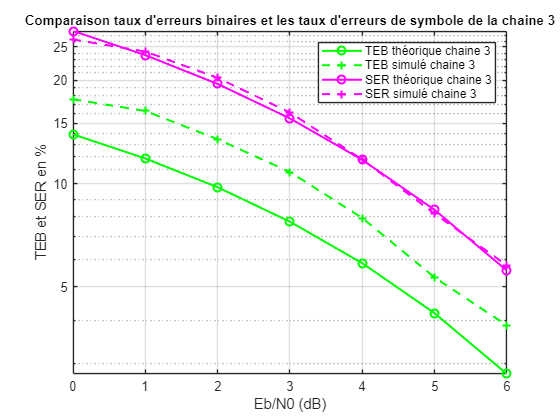


%% TRACÉS
figure;
semilogy(tab_Eb_sur_N0_dB, TEB_th_3*100,   'g-o',  'LineWidth', 1.5); hold on;
semilogy(tab_Eb_sur_N0_dB, TEB_simu_3*100, 'g--+', 'LineWidth', 1.5);
semilogy(tab_Eb_sur_N0_dB, SER_th_3*100,   'm-o',  'LineWidth', 1.5);
semilogy(tab_Eb_sur_N0_dB, SER_simu_3*100, 'm--+', 'LineWidth', 1.5);
xlabel('Eb/N0 (dB)'); ylabel('TEB et SER en %');
ytickformat('%.1f')
ax = gca;
ax.YTickLabel = string(ax.YTick);
legend('TEB théorique chaine 3', 'TEB simulé chaine 3', ...
       'SER théorique chaine 3', 'SER simulé chaine 3');
title('Comparaison taux d''erreurs binaires et les taux d''erreurs de symbole de la chaine 3', 'FontSize', 10);
grid on;

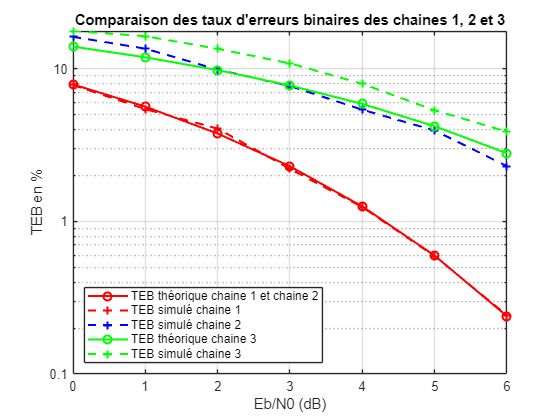


%%Comparaison TEB toutes chaines
figure;
semilogy(tab_Eb_sur_N0_dB, TEB_th_1*100,   'r-o',  'LineWidth', 1.5); hold on;
semilogy(tab_Eb_sur_N0_dB, TEB_simu_1*100, 'r--+', 'LineWidth', 1.5);
semilogy(tab_Eb_sur_N0_dB, TEB_simu_2*100, 'b--+', 'LineWidth', 1.5);
semilogy(tab_Eb_sur_N0_dB, TEB_th_3*100,   'g-o',  'LineWidth', 1.5);
semilogy(tab_Eb_sur_N0_dB, TEB_simu_3*100, 'g--+', 'LineWidth', 1.5);
xlabel('Eb/N0 (dB)'); ylabel('TEB en %');
ytickformat('%.1f')
ax = gca;
ax.YTickLabel = string(ax.YTick);
legend('TEB théorique chaine 1 et chaine 2', 'TEB simulé chaine 1','TEB simulé chaine 2','TEB théorique chaine 3', 'TEB simulé chaine 3', "Location", "southwest");
%legend('TEB théorique chaine 1 et chaine 2', 'TEB simulé chaine 1','TEB simulé chaine 2', "Location", "southwest");
title('Comparaison des taux d''erreurs binaires des chaines 1, 2 et 3');
grid on;

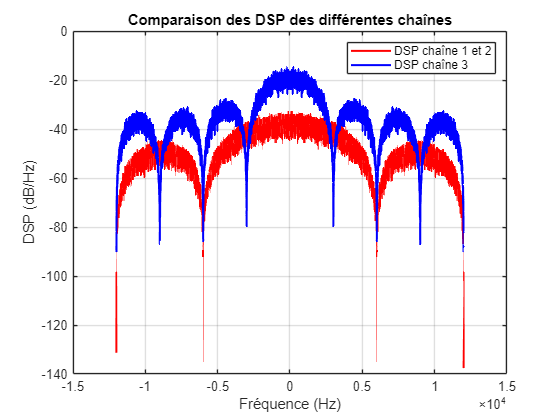

%% Figure 4 : DSP pour comparaison efficacite spectrale
bits_dsp     = randi([0,1], 1, 100000);

% Chaine 1
symboles_dsp = 2*bits_dsp - 1;
diracs_dsp   = kron(symboles_dsp, [1 zeros(1, Ns_1_2-1)]);
signal_1_dsp = filter(h_1_2, 1, diracs_dsp);

% Chaine 3
symboles_dsp_3 = (2 * bi2de(reshape(bits_dsp, 2, []).') - 3).';
diracs_dsp_3   = kron(symboles_dsp_3.', [1 zeros(1, Ns_3-1)]);
signal_3_dsp   = filter(h_3, 1, diracs_dsp_3);
figure;
[pxx1, f1] = pwelch(signal_1_dsp, [], [], [], Fe, 'centered');
[pxx3, f3] = pwelch(signal_3_dsp, [], [], [], Fe, 'centered');
plot(f1, 10*log10(pxx1), 'r', 'LineWidth', 1.5); hold on;
plot(f3, 10*log10(pxx3), 'b', 'LineWidth', 1.5);
xlabel('Fréquence (Hz)'); ylabel('DSP (dB/Hz)');
legend('DSP chaîne 1 et 2', 'DSP chaîne 3 ');
title('Comparaison des DSP des différentes chaînes');
grid on;